# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Reviewing real and img

- Why we need complex sinewave?

- Complex sine wave (or wavelet) comprises both a cosine (real) and sine (imaginary) component.

- Euler ’s formula allows you to represent complex numbers as points on a circle.

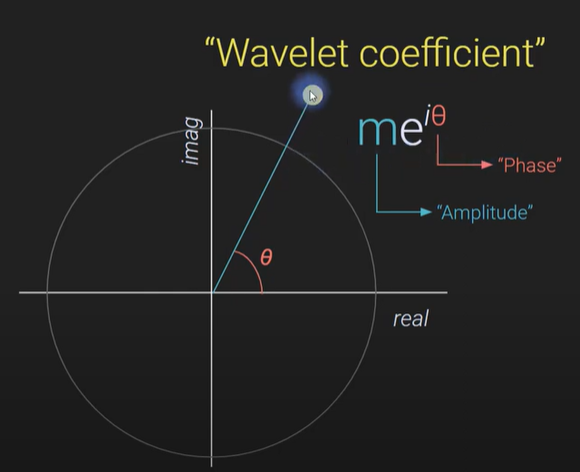

- Complex morlet wavelet.

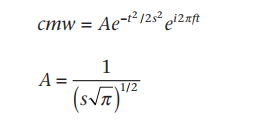

% parameters...
srate = 500; % sampling rate in Hz
f     = 10; % frequency of wavelet in Hz
time  = -1:1/srate:1; % time, from -1 to 1 second in steps of 1/sampling-rate
s     = 6/(2*pi*f);

% and together they make a wavelet
wavelet = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2)); 


% now show in 3d
figure
plot3(time,real(wavelet),imag(wavelet),'k')
xlabel('Time (ms)'), ylabel('real amplitude'), zlabel('imag amplitude')
title('3-D projection (click and spin with mouse)')
axis equal
rotate3d

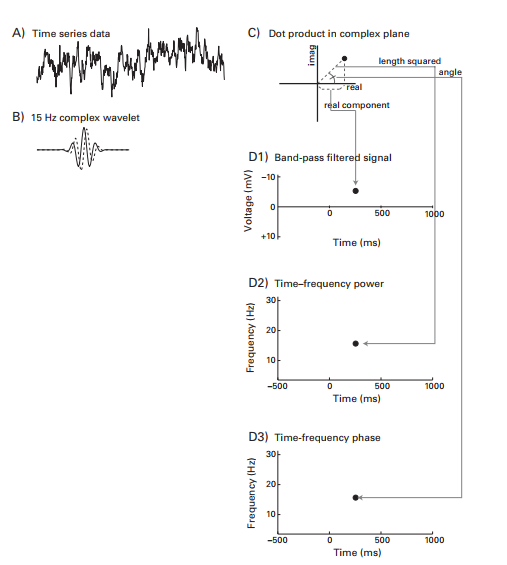

% create wavelet
load sampleEEGdata.mat
frequency = 6; % in Hz, as usual
time = -1:1/EEG.srate:1;
s    = (4/(2*pi*frequency))^2; % note that s is squared here rather than in the next line...
wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*s)/frequency);

% FFT parameters
n_wavelet            = length(wavelet);
n_data               = EEG.pnts;
n_convolution        = n_wavelet+n_data-1;
half_of_wavelet_size = (length(wavelet)-1)/2;

% FFT of wavelet and EEG data
fft_wavelet = fft(wavelet,n_convolution);
fft_data    = fft(squeeze(EEG.data(47,:,1)),n_convolution); % FCz, trial 1

convolution_result_fft = ifft(fft_wavelet.*fft_data,n_convolution) * sqrt(s);

% cut off edges
convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);

% plot for comparison
figure
subplot(311)
plot(EEG.times,real(convolution_result_fft))
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
title([ 'Projection onto real axis is filtered signal at ' num2str(frequency) ' Hz.' ])

subplot(312)
plot(EEG.times,abs(convolution_result_fft).^2)
xlabel('Time (ms)'), ylabel('Power (\muV^2)')
title([ 'Magnitude of projection vector squared is power at ' num2str(frequency) ' Hz.' ])

subplot(313)
plot(EEG.times,angle(convolution_result_fft))
xlabel('Time (ms)'), ylabel('Phase angle (rad.)')
title([ 'Angle of vector is phase angle time series at ' num2str(frequency) ' Hz.' ])

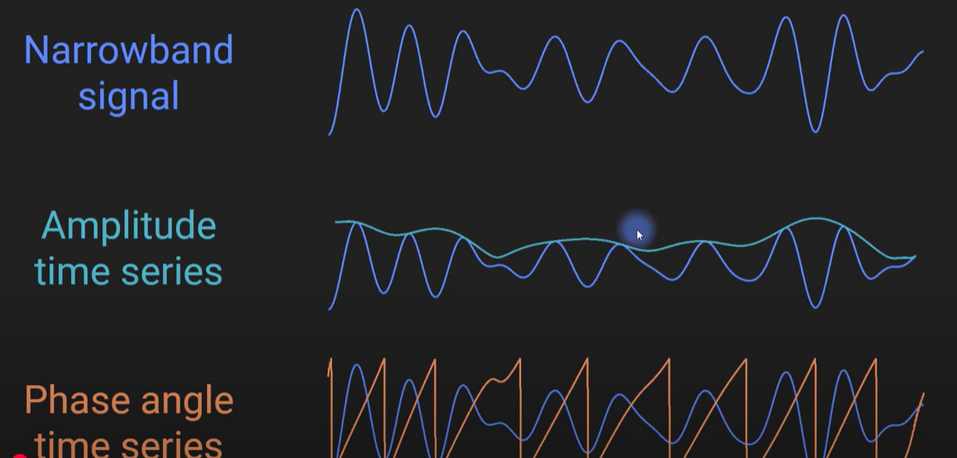

### Design Parameters for wavelet

**How Low Should the Lowest Frequency Be?**

This depends on your expectations about the results, on the task design and timing of trial events, and on the length of your data epochs.   

what freq is you interes? your time epoch?

"You should have at least several cycles worth of time to extract robust band-specific information. Thus, if you have 1-s epochs, estimates of activity below 4 Hz will have relatively low signal-to-noise ratio."

**How High Should the Highest Frequency Be?**  

This also depends on your expectations about the results as well as on the sampling rate. You cannot examine frequencies higher than the Nyquist frequency  

if you need to investigate alpha band, having frequency more than 50hz: increase analysis time and may produce timefrequency plots in which only a small portion of the plot is relevant. Furthermore, having additional frequencies that are not of interest will lead to more stringent statistical significance thresholding when correcting for multiple comparisons.  

**How Many Frequencies Should Be Used?**  

If you have a clear hypothesis about 10-Hz activity, you technically need only one wavelet. However, this might be a suboptimal analysis strategy because, for example, there might be individual differences in the exact frequency of the alpha activity. Having more frequencies gives you the freedom to select the appropriate frequency ranges based on the data, and it will also allow you to perform exploratory and post-hoc analyses in addition to the hypothesisbased analyses. On the other hand, more frequencies means larger results matrices, increased computation time, and increased requirements for multiple comparisons corrections.  

**Should Frequencies Be Linearly or Logarithmically Spaced?**  

You can specify the peak frequencies of wavelets to increase linearly (e.g., 5, 13, 22, 30 Hz), or logarithmically (e.g., 5, 9, 16.5, 30 Hz). Both are correct, although given that frequencies are often conceptualized on a logarithmic scale, it makes sense to use logarithmically spaced wavelet peak frequencies.  ** it changed how the plots appears**

If your main results concern lower-frequency activity, it is advisable to use logarithmic scaling because this will highlight the lower-frequency end of the spectrum (figure 13.11A); on the other hand, if your main results concern higher-frequency activity, it is advisable to use linear scaling because this will highlight the higher frequencies and visually minimize  the lower frequencies.

**How Long Should Wavelets Be?**  

This is an important issue, but it has an easy answer. Wavelets should be long enough such that the lowest-frequency wavelet tapers to zero (or extremely close to zero) at both the negative and positive ends of time.  

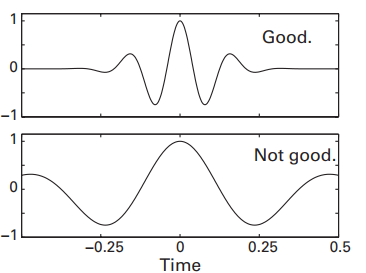

**How Many Cycles Should Be Used for the Gaussian Taper?**  

This parameter controls the trade-off between temporal and frequency precisions  

larger number of cycles gives you better frequency precision at the cost of worse temporal precision, and a smaller number of cycles gives you better temporal precision at the cost of worse frequency precision. This is the parameter that controls the Heisenberg uncertainty principle applied to time-frequency analysis: the more you know about *when *something happened, the less you know about *where *(i.e., at which frequency) it happened, and vice versa.  

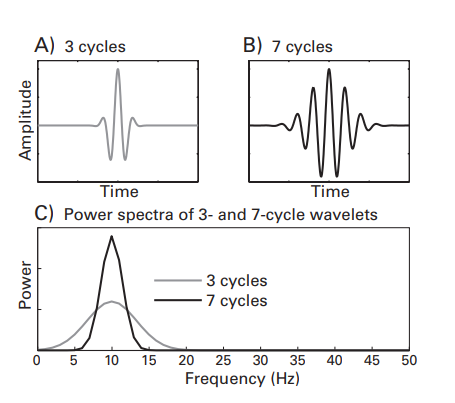

**Determining the Frequency Smoothing of Wavelets**  

It might be relevant to know how much frequency smoothing the wavelets apply to your data.  Because the wavelet has a Gaussian shape in the frequency domain, the extent to which neighboring frequencies contribute to the result of wavelet convolution can be reported in terms of full width at half-maximum (FWHM).  

FWHM refers to the frequency width for which the power is at 50% on the left and right sides of the peak (that is, the lower and upper 50% attenuation frequencies).   

where *σ *is the standard deviation of the frequency response.   


frex  = logspace(log10(2),log10(80),30);
srate = 500;
time  = -2:1/srate:2;
N     = length(time);
hz    = linspace(0,srate/2,floor(N/2)+1);
fwhm  = zeros(3,length(frex));

for numcyclesi = 1:3
    
    switch numcyclesi
        case 1
            numcycles=repmat(3,1,length(frex));
        case 2
            numcycles=repmat(10,1,length(frex));
        case 3
            numcycles=logspace(log10(3),log10(10),length(frex));
    end
    
    for fi=1:length(frex)
        
        % make wavelet
        wavelet = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(numcycles(fi)/(2*pi*frex(fi)))^2));
        
        % take FFT of wavelet
        fwave = fft(wavelet);
        fwave = abs(fwave(1:length(hz)))*2;
        
        % normalize power to [0 1]
        fwave = fwave-min(fwave);
        fwave = fwave/max(fwave);
        
        % find left and right 1/2
        [~,peakx]  = max(fwave); % if matlab crashes, replace "~" with "junk"
        [~,left5]  = min(abs(fwave(1:peakx)-.5));
        [~,right5] = min(abs(fwave(peakx:end)-.5));
        right5 = right5+peakx-1;
        
        fwhm(numcyclesi,fi) = hz(right5)-hz(left5);
        
        % plot one example of a wavelet's power spectrum and fwhm
        if fi==ceil(length(frex)/2) && numcyclesi==3
            figure
            
            % plot power spectrum
            plot(hz,fwave,'.-')
            hold on
            
            % plot fwhm
            plot(hz(left5),fwave(left5),'ro','markersize',10)
            plot(hz(right5),fwave(right5),'ro','markersize',10)
            % and draw lines to frequencies
            plot([hz(left5) hz(left5)],[0 fwave(left5)],'r')
            plot([hz(right5) hz(right5)],[0 fwave(right5)],'r')            
            
            set(gca,'xlim',[0 30])
            xlabel('Frequency (Hz)')
            ylabel('Normalized power')
        end
    end
end

figure
plot(frex,fwhm,'.-')
xlabel('Frequency (Hz)')
ylabel('FWHM (Hz)')
legend({'3';'10';'3-10'})

figure
plot(frex,fwhm,'.-')
xlabel('Frequency (Hz)')
ylabel('FWHM (Hz)')
legend({'3';'10';'3-10'})
set(gca,'xlim',[frex(1)*.8 frex(end)*1.2],'ylim',[min(fwhm(:))*.8 max(fwhm(:))*1.2],'xscale','log','xtick',round(logspace(log10(frex(1)),log10(frex(end)),6)),'yscale','log','ytick',round(10*logspace(log10(min(fwhm(:))),log10(max(fwhm(:))),6))/10)


**Tips for Writing Efficient Convolution Code in Matlab**  

Because the Fourier transform of the EEG data does not change as a function of frequency, the FFT of the data needs to be computed only once before looping over frequencies. This can save considerable time, particularly if you have a lot of data and many frequencies. In contrast, if you use the Matlab conv function, the FFT of the data will be redundantly recomputed at each iteration inside the frequency loop.

You can further decrease analysis time by using FFTs of an order that is a power of two. That is, the FFT of a 1024-point vector is faster to compute than the FFT of a 1023-point vector. Usually, data time series must be zero-padded to get to a length that is a power of two, so make sure you remove these extra points after convolution. The online Matlab code for this chapter shows you how to zero-pad FFTs and then remove the extra points after convolution.

Finally, you do not need to perform convolution on each trial separately; it is faster and more elegant to concatenate all trials into one long time series, perform one convolution with all trials, and then reshape the result back to a time-by-trials matrix. 

**Describing This Analysis in Your Methods Section**

If you perform a complex Morlet wavelet convolution to analyze your data, there are several important details to include in the Methods section, including the minimum, maximum, and number of frequencies of the wavelets; whether frequencies increased linearly or logarithmically; and the number of wavelet cycles and whether this changed as a function of frequency. Morlet wavelets are commonly used in the literature, so it is not necessary to include the equations in the Methods section unless you modify the standard equations. On the other hand, the equations for Morlet wavelets are brief, so there is little concern about exceeding journal space or word count limitations. You could also report the frequencydomain FWHM of the wavelets, although this is not typically done.  

### Exercise

1. Create a family of complex Morlet wavelets, ranging in frequencies from 2 Hz to 30 Hz in five steps.

2. Convolve each wavelet with EEG data from all electrodes and from one trial.

3. Extract power and phase from the result of complex wavelet convolution and store in a time × frequency × electrodes × power/phase matrix (thus, a 640 × 5 × 64 × 2 matrix).

4. Make topographical plots of power and phase at 180 ms at all frequencies (hint: you may need to use the squeeze function to remove singleton dimensions). Arrange the plots in one figure with five columns for frequency and two rows for power/phase. Put labels in the plot so it is clear which topographical maps correspond to which frequencies.

5. Repeat step 4 for activity at 360 ms.

6. Are there any prominent topographical features in power or in phase? Do these differ for different frequencies? Do power and phase have similar topographical distributions? Is there any reason to suspect that they might have similar or different topographies?

7. (Optional) Because phase values are circular (–*π *and +*π *are identical), most color maps are inappropriate because they suggest that –*π *and +*π *are very different values (represented, e.g., by blue and red colors). Create a circular colormap that can be used for phase values. You can do this by setting the red, green, and/or blue values to be a cosine function rather than a linear function. Recreate the phase topographical maps. Do they look any different with the new color maps?

### Hilbert Transform

The Hilbert transform allows you to ***extract a complex signal from a signal that contains only a real part.***  This is what the Matlab function hilbert does.   

Note: *The Matlab function hilbert will accept a matrix as input. This is useful to apply the Hilbert transform to many trials or many electrodes in one command. However, the Matlab hilbert function will always compute the FFT over the first dimension. Thus, you should make sure that the first dimension of your matrix contains time; you do not want to compute the Hilbert transform over trials or over electrodes.   *

### **Constructing a Filter**  

For creating filter FIR you can pass these steps:

Function: B=firls(N,F,A)

Input:

- The first input is the order parameter, which defines the length of the filter kernel (the length of kernel is the order plus one).  

- The second input to firls is a vector of frequencies that defines the shape of the response.

- the third input to firls is the “ ideal ” filter response amplitude. This is a vector comprising as many numbers as the second input and contains zeros for the frequencies you want to attenuate and ones for the frequencies you want to keep.   

Output:

Returns a length N+1 linear phase (real, symmetric coefficients) FIR filter which has the best approximation to the desired frequency response described by F and A in the least squares sense.

NOTE for input F:

For a bandpass filter, you can use six numbers: the** zero frequency**, the frequency of the **start of the lower transition zone**, the lower bound of the bandpass, the upper bound of the bandpass, the** frequency of the end of the upper transition zone**, and finally the **Nyquist frequency**. These numbers are scaled such that the **Nyquist frequency is 1.0;** thus, you can define this vector in frequencies in Hz and then divide the vector by the Nyquist frequency. For the function fir1, you enter only two numbers, the lower and upper bounds of the filter, because transition zones are set to zero.

Note for transition zone:

Sharp edges in the frequency domain can be avoided by using transition zones. If you use firls, the transition zones should be between 10% and 25% of the lower and upper frequency bounds. There is a trade-off for the width of the transition zones:** sharper transition zones give a better frequency response** but increase the **risk of introducing time-domain ringing artifacts**; gentler transition zones **decrease the risk of time-domain ringing artifacts** but also have l**ess frequency specificity.  **

load sampleEEGdata.mat
nyquist = EEG.srate/2;
center_freq = 20; % in Hz
filter_frequency_spread_wide = 10; % Hz +/- the center frequency
transition_width = 0.2;
hz_filtkern   = linspace(0,nyquist,101); % list of frequencies in Hz corresponding to filter kernel

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

figure
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

Comparing with Marlot wavelet

load sampleEEGdata.mat
nyquist = EEG.srate/2;
center_freq = 20; % in Hz
filter_frequency_spread  = 6; % Hz +/- the center frequency
wavelet_frequency_spread = 4; % number of wavelet cycles

% create wavelet...
time = -1000/EEG.srate/10:1/EEG.srate:1000/EEG.srate/10;
wavelet = zscore(exp(2*1i*pi*center_freq.*time) .* exp(-time.^2./(2*(wavelet_frequency_spread/(2*pi*center_freq))^2)));
% ... and compute its power spectrum
fft_wavelet = abs(fft(wavelet));
fft_wavelet = fft_wavelet./max(fft_wavelet); % normalized to 1.0 for visual comparison ease
hz_wavelet  = linspace(0,nyquist,length(time)/2+1);


% construct filter kernel (the mechanics of filter construction will be
% discussed in the text around figure 14.4)
transition_width = 0.2;
ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread) (center_freq-filter_frequency_spread) (center_freq+filter_frequency_spread) (1+transition_width)*(center_freq+filter_frequency_spread) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweights  = zscore(firls(200,ffrequencies,idealresponse));
% also compute weights using fir1
filterweights1 = zscore(fir1(200,[center_freq-filter_frequency_spread center_freq+filter_frequency_spread]./nyquist));
% compute its power spectrum
fft_filtkern  = abs(fft(filterweights));
fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
fft_filtkern1 = abs(fft(filterweights1));
fft_filtkern1 = fft_filtkern1./max(fft_filtkern1); % normalized to 1.0 for visual comparison ease

hz_filtkern   = linspace(0,nyquist,101); % list of frequencies in Hz corresponding to filter kernel


figure
subplot(211)

% plot wavelet and filter kernel
plot(real(wavelet))
hold on
plot(filterweights,'r')
legend({'wavelet';'filter kernel'})
set(gca,'xlim',[0 200],'ylim',[-5 5])
xlabel('Time')

% plot power spectra
subplot(212)
plot(hz_wavelet,fft_wavelet(1:ceil(length(fft_wavelet)/2)))
hold on
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'r')
legend({'wavelet';'filter kernel'})
set(gca,'ylim',[-.1 1.1])
xlabel('Frequency (Hz)')

bandpass filtering can provide extra frequency specificity compared to wavelets, and this is why wavelet convolution will generally produce timefrequency plots that appear a bit smoother over the frequency axis compared to timefrequency plots produced by the filter-Hilbert method.  

**Check your filters carefully before applying them.  **

center_freq = 60; % in Hz
filter_frequency_spread_wide = 10; % Hz +/- the center frequency

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

figure
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
title([ 'SSE: ' num2str(sum( (idealresponse-fft_filtkern(freqsidx)).^2 )) ])




center_freq = 60; % in Hz
filter_frequency_spread_wide = 15; % Hz +/- the center frequency

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

figure
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
title([ 'SSE: ' num2str(sum( (idealresponse-fft_filtkern(freqsidx)).^2 )) ])

### **Applying the Filter to Data** using Filtfilt

The next step in filtering EEG data is to apply that filter kernel to the data. This can be done using the Matlab function filtfilt. The inputs to the function filtfilt are the filter kernel, a scalar or vector of weighting coefficients, and the data time series. The filter kernel is the output of firls, and the weighting coefficient can be set to 1.0 unless you would like to apply a weighting to the filter kernel, which is not typically necessary for time-frequency decomposition of EEG data. The output of filtfilt is the filtered data.

help filtfilt

### **Filtering Each Trial versus Filtering Concatenated Trials**  

It is faster to concatenate all trials into one long time series, filter that concatenated time series, and then cut out the separate trials, compared to filtering each trial separately. Not only is it faster, it will also facilitate writing cleaner code, in part because it renders a loop over trials unnecessary.   

The main concern of trial concatenation is edge artifacts. If you use the filtfilt function, edge artifacts are less influential when performing single-trial filtering because Matlab’s filtfilt function reflects the time series data (see figure 7.3) to minimize edge artifacts. If you have sufficient buffer time at the start and end of trials, edge artifacts will subside by the time period you will analyze. You should avoid filtering concatenated trials if you have short epochs right around the time period in which you want to analyze (e.g., if your epochs are –200 to +800 ms around the event of interest); in this case, it is also possible to reflect the data on your own and then concatenate the reflected trials  

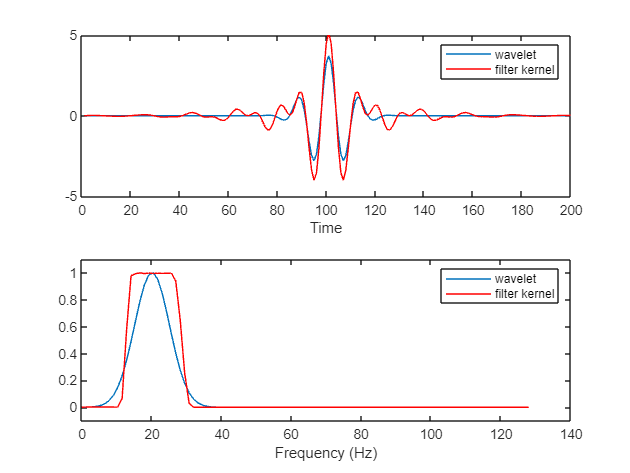

load sampleEEGdata.mat
srate = EEG.srate;
nyquist = srate/2;
elap_time = [0 0];
num_iter  = 100;


freqspread  =  4; % Hz +/- the center frequency
center_freq = 20;
transwid    = .15;

% construct filter kernels
ffrequencies  = [ 0 (1-transwid)*(center_freq-freqspread) (center_freq-freqspread) (center_freq+freqspread) (1+transwid)*(center_freq+freqspread) nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(3*round(EEG.srate/(center_freq-freqspread)),ffrequencies,idealresponse);


for i=1:num_iter
    tic
    data2filter_cat = squeeze(double(reshape(EEG.data(47,:,:),1,EEG.pnts*EEG.trials)));
    filtdat_cat = reshape(filtfilt(filterweights,1,data2filter_cat),EEG.pnts,EEG.trials);
    elap_time(1) = elap_time(1) + toc;
end

for i=1:num_iter
    tic
    data2filter_sep = squeeze(double(EEG.data(47,:,:)));
    filtdat_sep = zeros(size(data2filter_sep));
    for triali=1:EEG.trials
        filtdat_sep(:,triali) = filtfilt(filterweights,1,data2filter_sep(:,triali));
    end
    elap_time(2) = elap_time(2) + toc;
end


elap_time = elap_time/num_iter;

% plot
figure
plot(EEG.times,mean(filtdat_cat,2))
hold on
plot(EEG.times,mean(filtdat_sep,2),'r')
legend({'concatenated';'separated'})

figure
bar(elap_time)
set(gca,'xlim',[0 3],'xticklabel',{'Concatenated';'Separated'})
ylabel('Time (s)')
title([ 'Speed increase of ' num2str(elap_time(2)/elap_time(1)) '!' ])

**Exercises**

1. Pick two frequencies (e.g., 5 Hz and 25 Hz) and one electrode and perform complex Morlet wavelet convolution and filter-Hilbert using those two frequencies as the peak/center frequencies for all trials. Plot the resulting power and the bandpass-filtered signal (that is, the real component of the analytic signal) from each method. Plot one single trial (you can choose the trial randomly but plot the same trial for both methods) and then plot the average of all trials. Describe some similarities and differences between the results of the two time-frequency decomposition methods.

2. Modify the wavelet and filter settings (but keep the peak/center frequencies the same) until these two methods produce very similar results. Next, modify the wavelet and filter settings (except the peak/center frequencies) to make the results different (stay within a reasonable range of parameter settings; they do not need to look dramatically different). Which parameters did you change to make the results look more similar versus more different? How different are the results, and would you consider this a meaningful difference? What does this difference tell you about when to use specific parameter settings for wavelet convolution and the filter-Hilbert method?  